# Лабораторная работа №3

Численное интегрирование, метод трапеций.

f = @(x) exp(x);
d = [-1, 1];
get_int_trap(f, d, 5)
integral(f, d(1), d(2))

Построение зависимости от количества точек

Зависимость от параметра!

Вывод функции.

figure
hold on
Err = [];
for i = 1:2
    n = logspace(0, 6, 100);
    if i == 1
        f1 = @(x) sin(x)./x;
    else
        f1 = @(x) 1./x;
    end
    E = [];
    d = [1, 4];
    for i = 1:max(size(n))
        disp(i);
        eps = abs(get_int_trap(f1, d, n(i)) - integral(f1, d(1), d(2)));
        E(i) = eps;
    end
    Err = [Err; E];
    loglog(n, E, 'LineWidth', 1.5);
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100



     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100



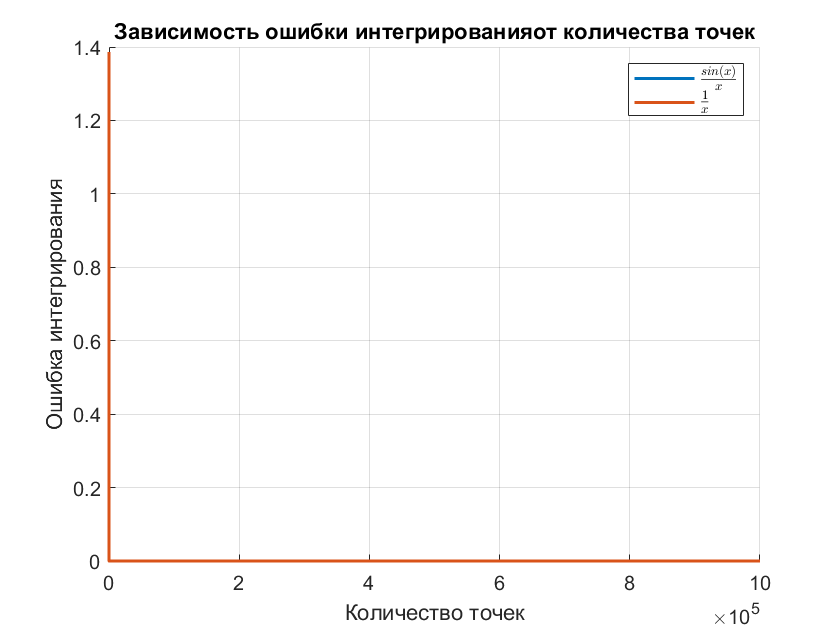

xlabel("Количество точек")
ylabel("Ошибка интегрирования")
title("Зависимость ошибки интегрирования" + ...
    "от количества точек")
grid on;
legend("$\frac{sin(x)}{x}$", "$\frac{1}{x}$", 'interpreter', 'latex')

Построение зависимости от параметра:

Err = [];
for j = 1:2
    n = linspace(1e-16, 3.999, 100);
    if i == 1
        f1 = @(x) sin(x)./x;
        syms x f;
        f(x) = sin(x)./x;
    else
        f1 = @(x) 1./x;
        syms x f;
        f(x) = 1./x;
    end
    E = [];
    for i = 1:max(size(n))
        d = [n(i), 4];
        eps = abs(get_int_trap(f, d, 100) - integral(f1, d(1), d(2)));
        E = [E eps];
        disp(i)
    end
    Err = [Err; E];
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25



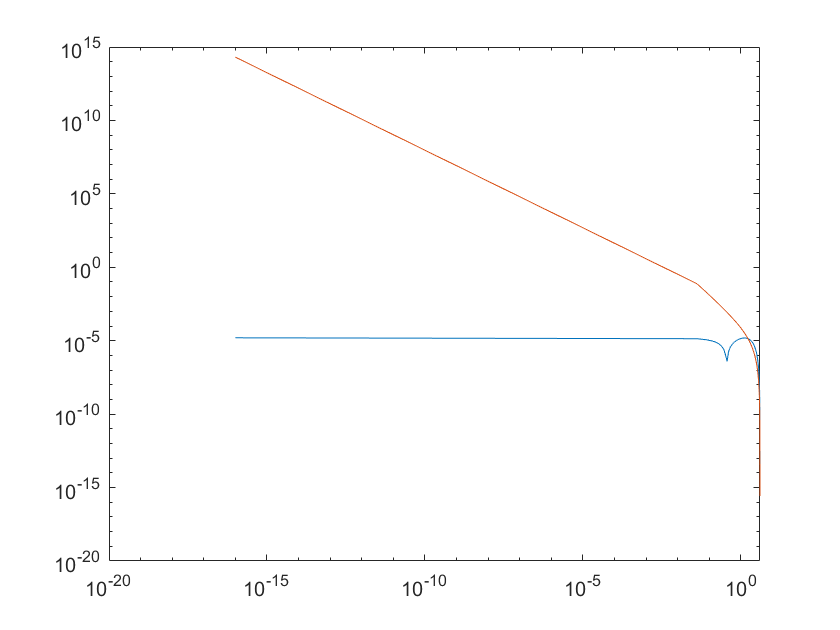

figure
grid on
loglog(n, Err(1, :))
hold on
loglog(n, Err(2, :))

function s = get_int_trap(f, d, n)
   X = linspace(d(1), d(2), n);
   s = 0;
   parfor i = 2:max(size(X))
       s = s + trap(f, X(i-1), X(i));
   end
end

function i = trap(f, a, b)
    i = (b - a)/2*(f(a) + f(b));
end